%% Parameters van de bol
R = 5;      % straal in meters (5 cm)
N = 15;        % resolutie, hoe hoger N hoe meer punten

linspace(0, pi, N)

ans =          0    0.2244    0.4488    0.6732    0.8976    1.1220    1.3464    1.5708    1.7952    2.0196    2.2440    2.4684    2.6928    2.9172    3.1416


linspace(0, 2*pi, 2*N)

ans =          0    0.2167    0.4333    0.6500    0.8666    1.0833    1.3000    1.5166    1.7333    1.9500    2.1666    2.3833    2.5999    2.8166    3.0333    3.2499    3.4666    3.6832    3.8999    4.1166    4.3332    4.5499    4.7666    4.9832    5.1999    5.4165    5.6332    5.8499    6.0665    6.2832



%% Maak sferische coördinaten
[theta, phi] = meshgrid(linspace(0, pi, N), linspace(0, 2*pi, 2*N))

theta =          0    0.2244    0.4488    0.6732    0.8976    1.1220    1.3464    1.5708    1.7952    2.0196    2.2440    2.4684    2.6928    2.9172    3.1416
         0    0.2244    0.4488    0.6732    0.8976    1.1220    1.3464    1.5708    1.7952    2.0196    2.2440    2.4684    2.6928    2.9172    3.1416
         0    0.2244    0.4488    0.6732    0.8976    1.1220    1.3464    1.5708    1.7952    2.0196    2.2440    2.4684    2.6928    2.9172    3.1416
         0    0.2244    0.4488    0.6732    0.8976    1.1220    1.3464    1.5708    1.7952    2.0196    2.2440    2.4684    2.6928    2.9172    3.1416
         0    0.2244    0.4488    0.6732    0.8976    1.1220    1.3464    1.5708    1.7952    2.0196    2.2440    2.4684    2.6928    2.9172    3.1416
         0    0.2244    0.4488    0.6732    0.8976    1.1220    1.3464    1.5708    1.7952    2.0196    2.2440    2.4684    2.6928    2.9172    3.1416
         0    0.2244    0.4488    0.6732    0.8976    1.1220    1.3464    1.5708    1.

phi =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167    0.2167
    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333    0.4333
    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500    0.6500
    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666    0.8666
    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833    1.0833
    1.3000    1.3000    1.3000    1.3000    1.3000    1.3000    1.3000    1.3000    1.30


%% Converteer naar cartesiaanse coördinaten
X = R * sin(theta) .* cos(phi)

X =          0    1.1126    2.1694    3.1174    3.9092    4.5048    4.8746    5.0000    4.8746    4.5048    3.9092    3.1174    2.1694    1.1126    0.0000
         0    1.0866    2.1187    3.0446    3.8178    4.3995    4.7607    4.8831    4.7607    4.3995    3.8178    3.0446    2.1187    1.0866    0.0000
         0    1.0098    1.9689    2.8293    3.5479    4.0885    4.4241    4.5379    4.4241    4.0885    3.5479    2.8293    1.9689    1.0098    0.0000
         0    0.8857    1.7271    2.4818    3.1121    3.5863    3.8807    3.9805    3.8807    3.5863    3.1121    2.4818    1.7271    0.8857    0.0000
         0    0.7203    1.4045    2.0182    2.5307    2.9164    3.1558    3.2369    3.1558    2.9164    2.5307    2.0182    1.4045    0.7203    0.0000
         0    0.5212    1.0162    1.4602    1.8311    2.1101    2.2833    2.3420    2.2833    2.1101    1.8311    1.4602    1.0162    0.5212    0.0000
         0    0.2977    0.5804    0.8340    1.0458    1.2052    1.3041    1.3376    1.3041

Y = R * sin(theta) .* sin(phi);
Z = R * cos(theta);

%% Zet alles in een N*3 matrix
sphere_ptcld = [X(:), Y(:), Z(:)];

%% Verwijder eventueel dubbele rijen
sphere_ptcld = unique(sphere_ptcld, 'rows');

%% Stuur naar base workspace (voor gebruik in Simscape)20
assignin('base', 'sphere_ptcld', sphere_ptcld);

figure;
scatter3(sphere_ptcld(:,1), sphere_ptcld(:,2), sphere_ptcld(:,3), 20, 'filled');50

ans = 50

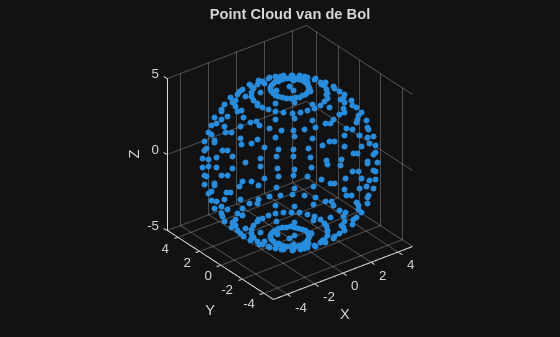

axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Point Cloud van de Bol');
grid on;

ksea = 70;
kd = 5;
cd = 1.67;
Jd = 0.01;